global me hbar V0 a d

me = 5.68572e-32;  hbar = 6.58199e-16;
c  = 2.99792458e18;        % velocidad de la luz en A/s
a  = 4.05/sqrt(3);         % distancia entre planos (111) del Al = 2.3383 A
d  = a/2;
V0 = 0;                    % electron libre

path('C:\Users\edgau\OneDrive - CINVESTAV\Documentos\MATLAB\Examen Max',path);

% Estilo comun de todas las figuras: lineas mas gruesas y letra mas grande.
set(groot, 'defaultLineLineWidth', 2)
set(groot, 'defaultAxesLineWidth', 1)
set(groot, 'defaultAxesFontSize', 12)


Electrón libre: zona reducida y zona extendida

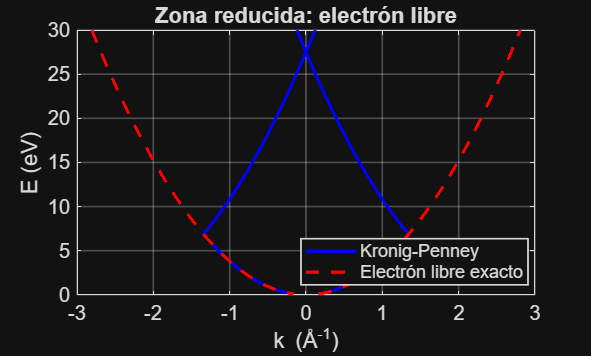

V0 = 0;             % electron libre: sin barrera
E = 0.1:0.01:30;    % eV

% La estructura de bandas lleva k en la abscisa y E en la ordenada,
% de modo que k(E) es el primer argumento de plot.
%
% E(k) es par en k: la rama k < 0 es el reflejo de la positiva, y hay que
% construirla porque acos solo devuelve valores en [0, pi]. El NaN separa
% las dos ramas; sin el, plot las une con un segmento horizontal que no
% forma parte de la solucion.
rk  = k(E);
kk  = [-fliplr(rk), NaN, rk];
EE  = [ fliplr(E),  NaN,  E];

kl  = fek(E);
kkl = [-fliplr(kl), NaN, kl];

figure
plot(kk, EE, 'b', kkl, EE, 'r--')
xlabel('k (Å^{-1})')
ylabel('E (eV)')
title('Zona reducida: electrón libre')
legend('Kronig-Penney', 'Electrón libre exacto', 'Location', 'best')
grid on

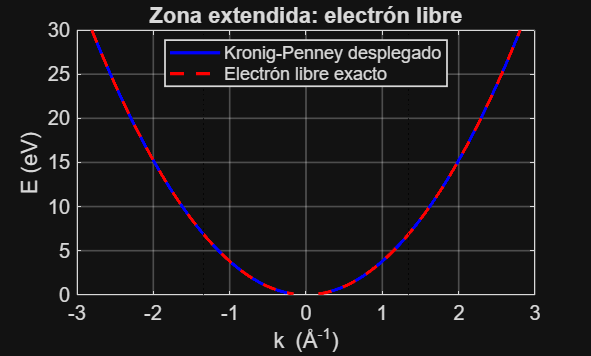


% Esquema de zona extendida: kext despliega cada banda a su intervalo
% [(n-1)pi/a, n pi/a] en lugar de plegarlas todas en la primera zona.
ke  = kext(E);
kke = [-fliplr(ke), NaN, ke];

figure
plot(kke, EE, 'b', kkl, EE, 'r--')
xline([-pi/a pi/a], 'k:')          % bordes de la primera zona
xlabel('k (Å^{-1})')
ylabel('E (eV)')
title('Zona extendida: electrón libre')
legend('Kronig-Penney desplegado', 'Electrón libre exacto', 'Location', 'best')
grid on


% Con V0 = 0 el desplegado reproduce la parabola libre: la diferencia es
% del orden de 1e-13.
max(abs(kext(E) - fek(E)))

ans = 3.1086e-14

Electrón casi libre

a = 4.05/sqrt(3);   % el periodo es la distancia entre planos (111)
d = a/2;

% La barrera es baja comparada con la energia cinetica en el borde de la
% primera zona, que es la escala con la que hay que comparar V0.
Eborde = (hbar^2/(2*me))*(pi/a)^2

Eborde = 6.8772


% Paso fino: con 0.1 eV la brecha de ~0.06 eV no se resuelve.
E = 0.001:1e-4:30;

for v = [0.1 0.2]
    V0 = v;                            % V0 es global: no puede ser indice del for
    [Ef, Et, E2] = bordes(E);
    Eg = E2 - Et;
    V1 = (V0/pi)*sin(pi*d/a);          % ecuacion (12)
    fprintf('V0=%.2f  Eg=%.5f  2|V1|=%.5f  cociente=%.3f\n', V0, Eg, 2*abs(V1), Eg/(2*abs(V1)));
end

V0=0.10  Eg=0.06370  2|V1|=0.06366  cociente=1.001
V0=0.20  Eg=0.12740  2|V1|=0.12732  cociente=1.001


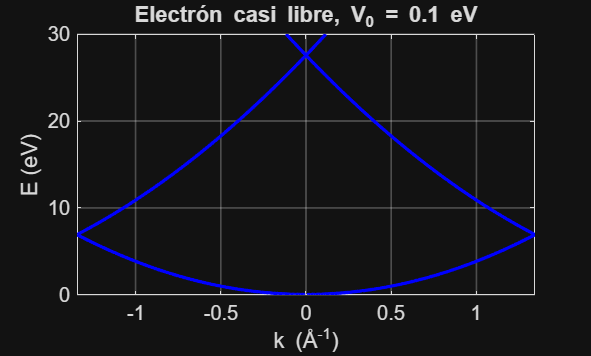


V0 = 0.1;
rk = k(E);

% Rama k < 0 por reflexion, porque E(k) = E(-k).
kk = [-fliplr(rk), NaN, rk];
EE = [ fliplr(E),  NaN,  E];

figure
plot(kk, EE, 'b')
xlabel('k (Å^{-1})')
ylabel('E (eV)')
title('Electrón casi libre, V_0 = 0.1 eV')
xlim([-pi/a pi/a])
grid on

Potencial fuerte y estados de superficie

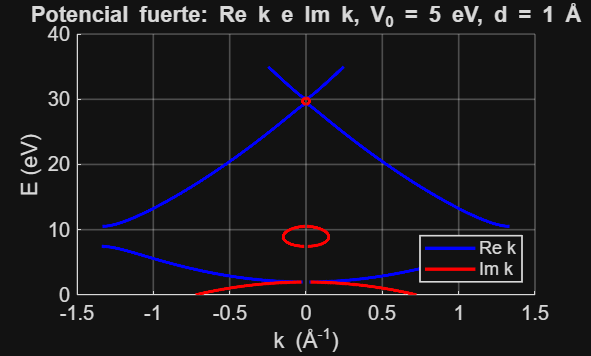

a  = 4.05/sqrt(3);
d  = 1;
V0 = 5;
E  = 0.01:0.005:35;         % malla fina: con 0.1 eV una brecha chica no se resuelve

[rk, ik] = k(E);
ik = abs(ik);               % la rama de acos cambia de signo segun si F > 1 o F < -1
ik(ik == 0) = NaN;          % no dibujar la linea de ceros dentro de las bandas

% Rama k < 0 por reflexion. En Re k es la onda reflejada; en Im k, el
% estado que decae desde la superficie opuesta del cristal.
kk  = [-fliplr(rk), NaN, rk];
kki = [-fliplr(ik), NaN, ik];
EE  = [ fliplr(E),  NaN,  E];

figure
hold on
plot(kk,  EE, 'b')          % bandas permitidas
plot(kki, EE, 'r')          % estados evanescentes en las brechas
hold off
xlabel('k (Å^{-1})')
ylabel('E (eV)')
title('Potencial fuerte: Re k e Im k, V_0 = 5 eV, d = 1 Å')
legend('Re k', 'Im k', 'Location', 'southeast')
grid on

Velocidad de grupo y masa efectiva

a  = 4.05/sqrt(3);
d  = a/2;
V0 = 0.1;

[Ef, Et] = bordes(0.001:1e-4:30);
E  = linspace(Ef + 1e-3, Et - 1e-3, 200001);   % solo la primera banda
dk = gradient(k(E), E);                        % dk/dE
vg = 1./(hbar*dk);                             % ecuacion (14)
ms = -(hbar^2)*dk.^3./(me*gradient(dk, E));    % ecuacion (15)

fprintf('vg max = %.4e A/s = %.3f%% de c\n', max(abs(vg)), 100*max(abs(vg))/c);

vg max = 1.5147e+16 A/s = 0.505% de c


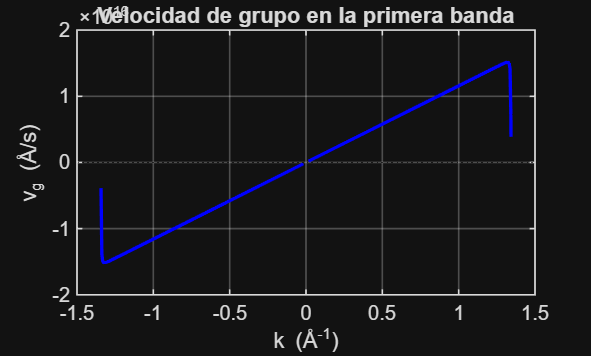


% vg es impar en k: al reflejar a k < 0 cambia de signo, que es el mismo
% electron viajando en sentido contrario.
rk = k(E);
kk = [-fliplr(rk), NaN, rk];
vv = [-fliplr(vg), NaN, vg];

figure
plot(kk, vv, 'b')
yline(0, 'k:')
xlabel('k (Å^{-1})')
ylabel('v_g (Å/s)')
title('Velocidad de grupo en la primera banda')
grid on

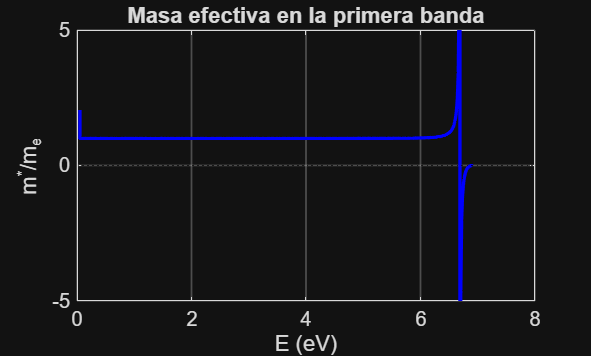


figure
plot(E, ms, 'b')
yline(0, 'k:')
ylim([-5 5])
xlabel('E (eV)')
ylabel('m^*/m_e')
title('Masa efectiva en la primera banda')
grid on